# MAE 158 Drag Calculator

#### Shashwat Sparsh

#### ID: 21697442

### `Skin Friction Drag Coeff`

#### Setup

hp_aircraft = 1;
T = 400;
%P = 1;  % via Table A.2
R = 1716;
rho = 0.0008754;

speedSound = sqrt(1.4*R*T)

speedSound = 980.2857

V = [230:10:880]%765;

V =    230   240   250   260   270   280   290   300   310   320   330   340   350   360   370   380   390   400   410   420   430   440   450   460   470   480   490   500   510   520   530   540   550   560   570   580   590   600   610   620   630   640   650   660   670   680   690   700   710   720


M = V/speedSound    % Mach Number

M =     0.2346    0.2448    0.2550    0.2652    0.2754    0.2856    0.2958    0.3060    0.3162    0.3264    0.3366    0.3468    0.3570    0.3672    0.3774    0.3876    0.3978    0.4080    0.4182    0.4284    0.4386    0.4488    0.4590    0.4693    0.4795    0.4897    0.4999    0.5101    0.5203    0.5305    0.5407    0.5509    0.5611    0.5713    0.5815    0.5917    0.6019    0.6121    0.6223    0.6325    0.6427    0.6529    0.6631    0.6733    0.6835    0.6937    0.7039    0.7141    0.7243    0.7345



Sref = 1000;

%CRexp = [];
%K = [];
%Cf = [];
%f = [];

%% Characteristic Lengths
MACexpW = 0;
MACexph = 0;
MACexpv = 0;
Lc = [MACexpW, MACexph, MACexpv, 16.2, 16.8];

%% Ratios
Lf = 119;
Df = 11;
ratios = [0.12, 0.09, 0.09, 0.06, Lf/Df, 5]  % Thickness and Fineness

ratios =     0.1200    0.0900    0.0900    0.0600   10.8182    5.0000


sigma = [0.2, 0.35, 0.8, 1] % Taper

sigma =     0.2000    0.3500    0.8000    1.0000



%% Sexp
Sexpw = 0;  % Defined Later on
Sexp = [Sexpw, 261, 161]

Sexp =      0   261   161



%% Swet
Swet = [0, 0, 0, 117, 0, 455]

Swet =      0     0     0   117     0   455


#### Wing

bW = 93.2;                      % Span
tcW = 0.18;
sweepangleW = 28;               % Sweep Angle
sigmaW = 0.2;                   % Taper Ratio: cT/cR
CRW = 17.8;                     % Root Chord
Coverage_wing = .17;            % Percent Covered
Rfuse = 11/2;

% Getting Swet %
SexpW = (1-Coverage_wing)*Sref;
SwetW = SWET(SexpW);

% Getting Skin Friction Coefficient %
CTW = sigmaW * CRW;
CRexp_wing = CREXP(CRW, CTW, Rfuse, bW);
MACexpW = MAC(CRexp_wing,CTW)

MACexpW = 11.1755

 
RNw = ReynoldsNumber(V, MACexpW);
Cf_w = CF(RNw);

% Getting Form Factor %
Kwing = Kairfoil(tcW, M, sweepangleW)

Kwing = 1.4572


% Calculating f and adding to array %
fwing = F(Kwing, Cf_w, SwetW)

fwing =     7.7743    7.7206    7.6696    7.6210    7.5746    7.5304    7.4880    7.4473    7.4083    7.3708    7.3347    7.2999    7.2663    7.2339    7.2026    7.1723    7.1429    7.1144    7.0868    7.0600    7.0340    7.0087    6.9841    6.9601    6.9368    6.9141    6.8919    6.8703    6.8492    6.8286    6.8085    6.7888    6.7695    6.7507    6.7323    6.7143    6.6967    6.6794    6.6624    6.6458    6.6295    6.6135    6.5979    6.5825    6.5674    6.5525    6.5379    6.5236    6.5096    6.4957


#### Horizontal Tail

SexpH = 261;
tcH = 0.09;
sweepangleH = 31.6;             % Sweep Angle
sigmaH = 0.35;                  % Wing Taper Ratio
CRH = 11.1;                     % Root Chord

% Getting Swet %
SwetH = SWET(SexpH);

% Getting Skin Friction Coefficient %
CTH = sigmaH * CRH;
MACexpH = MAC(CRH,CTH)

MACexpH = 8.0715

 
RNh = ReynoldsNumber(V, MACexpH);
Cf_h = CF(RNh);

% Getting Form Factor %
Khoriztail = Kairfoil(tcH, M, sweepangleH)

Khoriztail = 1.1720


% Calculating f and adding to array %
fhoriztail = F(Khoriztail, Cf_h, SwetH)

fhoriztail =     2.0744    2.0598    2.0459    2.0327    2.0200    2.0080    1.9964    1.9854    1.9748    1.9646    1.9547    1.9453    1.9362    1.9273    1.9188    1.9106    1.9026    1.8949    1.8874    1.8801    1.8730    1.8661    1.8595    1.8530    1.8466    1.8404    1.8344    1.8286    1.8228    1.8172    1.8118    1.8064    1.8012    1.7961    1.7911    1.7862    1.7814    1.7767    1.7721    1.7676    1.7632    1.7589    1.7546    1.7505    1.7464    1.7423    1.7384    1.7345    1.7307    1.7269


#### Vertical Tail

SexpV = 161;
tcV = 0.09;
sweepangleV = 43.5;             % Sweep Angle 
sigmaV = 0.8;                   % Wing Taper Ratio
CRV = 15.5;                     % Root Chord

% Getting Swet %
SwetV = SWET(SexpV);

% Getting Skin Friction Coefficient %
CTV = sigmaV * CRV;
MACexpV = MAC(CRV,CTV)

MACexpV = 14.0074

 
RNv = ReynoldsNumber(V, MACexpV);
Cf_v = CF(RNv);

% Getting Form Factor %
Kverttail = Kairfoil(tcV, M, sweepangleV)

Kverttail = 1.1354


% Calculating f and adding to array %
fverttail = F(Kverttail, Cf_v, SwetV)

fverttail =     1.1328    1.1251    1.1177    1.1107    1.1041    1.0977    1.0916    1.0858    1.0802    1.0748    1.0696    1.0646    1.0597    1.0551    1.0506    1.0462    1.0420    1.0379    1.0339    1.0301    1.0263    1.0227    1.0191    1.0157    1.0123    1.0091    1.0059    1.0028    0.9997    0.9967    0.9938    0.9910    0.9882    0.9855    0.9829    0.9803    0.9777    0.9753    0.9728    0.9704    0.9681    0.9658    0.9635    0.9613    0.9591    0.9570    0.9549    0.9528    0.9508    0.9488


#### Pylons

SwetP = 117;                    % Wetted Area
tcP = 0.06;
sweepangleP = 0;                % Sweep Angle
sigmaP = 1;                     % Taper Ratio: cT/cR
chordP = 16.2;                  % Chord

% Getting Skin Friction Coefficient %
RNp = ReynoldsNumber(V, chordP);
Cf_p = CF(RNp);

% Getting Form Factor %
Kpylon = Kairfoil(tcP, M, sweepangleP)

Kpylon = 1.1514


% Calculating f and adding to array %
fpylon = F(Kpylon, Cf_p, SwetP)

fpylon =     0.3998    0.3971    0.3945    0.3921    0.3898    0.3875    0.3854    0.3833    0.3814    0.3795    0.3777    0.3759    0.3742    0.3726    0.3710    0.3695    0.3680    0.3666    0.3652    0.3638    0.3625    0.3613    0.3600    0.3588    0.3576    0.3565    0.3554    0.3543    0.3532    0.3522    0.3512    0.3502    0.3492    0.3482    0.3473    0.3464    0.3455    0.3446    0.3438    0.3430    0.3421    0.3413    0.3405    0.3398    0.3390    0.3382    0.3375    0.3368    0.3361    0.3354


#### Fuselage

Lf = 105;
Df = 11;

% Calculating Swet %
SwetF = 0.8 * pi * Df * Lf;

% Getting Skin Friction Coefficient %
RNf = ReynoldsNumber(V, Lf);
Cf_f = CF(RNf)

Cf_f =     0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0021    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0020    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019    0.0019



% Getting Form Factor %
ratioF = Lf/Df

ratioF = 9.5455

Kfuse = KFR(ratioF);           % Via Digitized Figure 11.4

% Calculating f and adding to array %
ffuselage = F(Kfuse, Cf_f, SwetF)

ffuselage =     7.1882    7.1447    7.1033    7.0638    7.0261    6.9901    6.9556    6.9224    6.8906    6.8599    6.8304    6.8019    6.7744    6.7479    6.7222    6.6973    6.6732    6.6498    6.6271    6.6050    6.5836    6.5627    6.5424    6.5227    6.5034    6.4846    6.4663    6.4484    6.4310    6.4139    6.3973    6.3810    6.3650    6.3494    6.3342    6.3192    6.3045    6.2902    6.2761    6.2623    6.2487    6.2355    6.2224    6.2096    6.1970    6.1846    6.1725    6.1606    6.1488    6.1373


#### Nacelles

% Swet %
SwetN = 455;

% Getting Skin Friction Coefficient %
Ln = 16.8

Ln = 16.8000

RNn = ReynoldsNumber(V, 16.8);
Cf_n = CF(RNn)

Cf_n =     0.0030    0.0029    0.0029    0.0029    0.0029    0.0029    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0028    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0026    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025    0.0025



% Getting Form Factor %
ratioN = 5;
Knacelle = KFR(ratioN);           % Via Digitized Figure 11.4

% Calculating f and adding to array %
fnacelle = F(Knacelle, Cf_n, SwetN)

fnacelle =     1.7339    1.7222    1.7111    1.7006    1.6905    1.6809    1.6716    1.6628    1.6543    1.6461    1.6382    1.6307    1.6233    1.6163    1.6095    1.6028    1.5964    1.5902    1.5842    1.5784    1.5727    1.5672    1.5618    1.5566    1.5515    1.5465    1.5417    1.5370    1.5323    1.5278    1.5235    1.5192    1.5150    1.5108    1.5068    1.5029    1.4990    1.4952    1.4915    1.4879    1.4844    1.4809    1.4774    1.4741    1.4708    1.4675    1.4643    1.4612    1.4581    1.4551


#### Total Skin Friction

ftotal = fwing + fhoriztail + fverttail + fpylon + ffuselage + fnacelle;
CDP_total = ftotal./Sref

CDP_total =     0.0203    0.0202    0.0200    0.0199    0.0198    0.0197    0.0196    0.0195    0.0194    0.0193    0.0192    0.0191    0.0190    0.0190    0.0189    0.0188    0.0187    0.0187    0.0186    0.0185    0.0185    0.0184    0.0183    0.0183    0.0182    0.0182    0.0181    0.0180    0.0180    0.0179    0.0179    0.0178    0.0178    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0174    0.0174    0.0174    0.0173    0.0173    0.0172    0.0172    0.0172    0.0171    0.0171


### `Induced Drag Coeff`

% Getting CL %
W = 98000;              % Aircraft Weight
q = 0.5 * rho * (V.^2);  % Dynamic Pressure
CL = W ./ (q * Sref)     % Coeff of Lift

CL =     4.2325    3.8871    3.5824    3.3121    3.0713    2.8558    2.6623    2.4878    2.3298    2.1865    2.0560    1.9368    1.8277    1.7276    1.6355    1.5505    1.4720    1.3994    1.3319    1.2693    1.2109    1.1565    1.1057    1.0581    1.0136    0.9718    0.9325    0.8956    0.8608    0.8280    0.7971    0.7678    0.7402    0.7140    0.6891    0.6656    0.6432    0.6219    0.6017    0.5825    0.5641    0.5466    0.5299    0.5140    0.4988    0.4842    0.4703    0.4569    0.4442    0.4319



% Getting Aspect Ratio %
ARw = (bW^2)/Sref

ARw = 8.6862


% Getting CDi %
e = 1;                          % Oswald Efficiency Factor
CDi = (CL.^2) / (pi * ARw * e)   % Coeff of Induced Drag

CDi =     0.6565    0.5537    0.4703    0.4020    0.3457    0.2989    0.2597    0.2268    0.1989    0.1752    0.1549    0.1375    0.1224    0.1094    0.0980    0.0881    0.0794    0.0718    0.0650    0.0590    0.0537    0.0490    0.0448    0.0410    0.0376    0.0346    0.0319    0.0294    0.0272    0.0251    0.0233    0.0216    0.0201    0.0187    0.0174    0.0162    0.0152    0.0142    0.0133    0.0124    0.0117    0.0109    0.0103    0.0097    0.0091    0.0086    0.0081    0.0077    0.0072    0.0068


## `Total Drag & Lift/Drag Ratio`

ProfileDrag = CDP_total .* q .* Sref

ProfileDrag = 	1.0e+03 *

    0.4701    0.5085    0.5483    0.5894    0.6319    0.6758    0.7211    0.7677    0.8156    0.8648    0.9154    0.9673    1.0206    1.0751    1.1310    1.1881    1.2466    1.3064    1.3674    1.4297    1.4933    1.5582    1.6244    1.6918    1.7605    1.8305    1.9017    1.9742    2.0479    2.1229    2.1991    2.2765    2.3552    2.4352    2.5163    2.5987    2.6823    2.7672    2.8533    2.9405    3.0290    3.1188    3.2097    3.3018    3.3952    3.4897    3.5854    3.6824    3.7805    3.8799


InducedDrag = CDi .* q .* Sref

InducedDrag = 	1.0e+04 *

    1.5200    1.3960    1.2865    1.1895    1.1030    1.0256    0.9561    0.8934    0.8367    0.7852    0.7384    0.6956    0.6564    0.6204    0.5873    0.5568    0.5286    0.5025    0.4783    0.4558    0.4349    0.4153    0.3971    0.3800    0.3640    0.3490    0.3349    0.3216    0.3091    0.2974    0.2862    0.2757    0.2658    0.2564    0.2475    0.2390    0.2310    0.2234    0.2161    0.2092    0.2026    0.1963    0.1903    0.1846    0.1791    0.1739    0.1689    0.1641    0.1595    0.1551


CDtotal = CDP_total + CDi

CDtotal =     0.6768    0.5739    0.4903    0.4219    0.3655    0.3186    0.2793    0.2463    0.2183    0.1945    0.1741    0.1566    0.1415    0.1283    0.1169    0.1069    0.0981    0.0904    0.0836    0.0776    0.0722    0.0674    0.0631    0.0593    0.0559    0.0528    0.0500    0.0474    0.0451    0.0431    0.0412    0.0394    0.0379    0.0364    0.0351    0.0339    0.0328    0.0317    0.0308    0.0299    0.0291    0.0283    0.0276    0.0270    0.0264    0.0258    0.0253    0.0248    0.0244    0.0239


TotalDrag = CDtotal .* q .* Sref

TotalDrag = 	1.0e+04 *

    1.5670    1.4468    1.3413    1.2484    1.1662    1.0932    1.0282    0.9702    0.9183    0.8717    0.8299    0.7923    0.7584    0.7279    0.7004    0.6757    0.6533    0.6332    0.6151    0.5988    0.5842    0.5711    0.5595    0.5492    0.5400    0.5320    0.5251    0.5190    0.5139    0.5096    0.5062    0.5034    0.5013    0.4999    0.4991    0.4989    0.4992    0.5001    0.5014    0.5032    0.5055    0.5082    0.5113    0.5148    0.5186    0.5229    0.5274    0.5323    0.5376    0.5431


L = W

L = 98000

LiftToDrag = L ./ TotalDrag

LiftToDrag =     6.2540    6.7735    7.3061    7.8501    8.4036    8.9646    9.5313   10.1013   10.6724   11.2423   11.8087   12.3691   12.9212   13.4627   13.9912   14.5045   15.0006   15.4774   15.9332   16.3662   16.7750   17.1584   17.5153   17.8449   18.1465   18.4198   18.6646   18.8808   19.0688   19.2289   19.3616   19.4677   19.5479   19.6033   19.6347   19.6434   19.6305   19.5972   19.5447   19.4742   19.3871   19.2844   19.1675   19.0376   18.8957   18.7430   18.5806   18.4095   18.2306   18.0448


## `Plots`

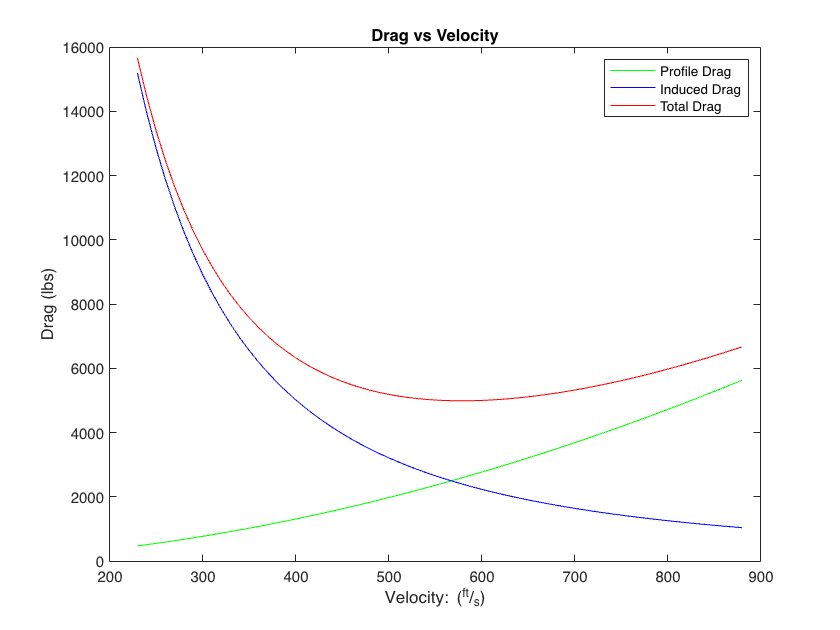

hold off;
plot(V, ProfileDrag, 'g', V, InducedDrag, 'b', V, TotalDrag, 'r')
title("Drag vs Velocity")
ylabel("Drag (lbs)")
xlabel("Velocity: (^{ft}/_{s})")
legend("Profile Drag", "Induced Drag", "Total Drag")

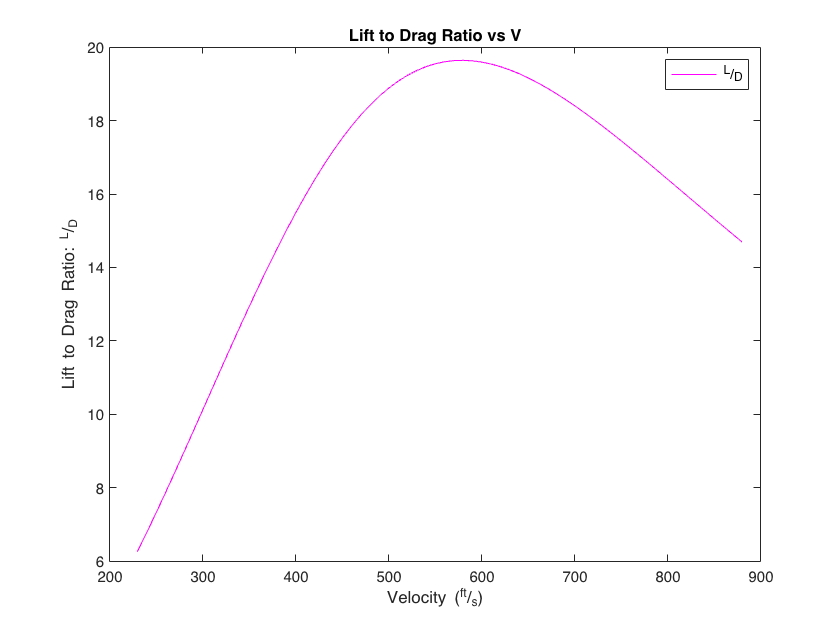


plot(V,LiftToDrag, 'm')
title("Lift to Drag Ratio vs V")
ylabel("Lift to Drag Ratio: ^{L}/_{D}")
xlabel("Velocity (^{ft}/_{s})")
legend("^{L}/_{D}")

## `Functions`

#### Reynolds Number Function

function RN = ReynoldsNumber(Velocity, characteristicLength)
    mu = 3.025E-7;
    rho = 0.0008754;
    V = Velocity;
    Lc = characteristicLength;
    RN = (rho * V * Lc)/mu;
end

#### Swet Function

function Swet = SWET(Sexp)
    Swet = 2 * 1.02 * Sexp;
end

#### MAC Function

function cbar = MAC(cR, cT)
    cbar= (2/3) * (cR + cT - ((cR*cT)/(cR+cT)));
end

#### CR Exposed Function

function crexp = CREXP(cR, cT, y, b)
    crexp = cR - ((cR- cT)*(2*(y/b)));
end

#### Skin Friction Coefficient

function Cf = CF(RN)
    Cf = 0.455 ./ ((log10(RN)).^2.58);
end

#### Form Factor for Airfoils

function K = Kairfoil(tc, Mo, sweepAngle)
    numTerm = (2-Mo.^2) * cosd(sweepAngle);
    denTerm = sqrt(1-(Mo*cosd(sweepAngle)^2));
    Z = numTerm/denTerm;
    K = 1 + (Z * tc) + (100*tc^4);
end

#### Form Factor via Fineness Ratio

function K = KFR(LbyD)
    K = 1.991*LbyD^-1.024+0.9084;
    % General model Power2:
    % Coefficients (with 95% confidence bounds):
    %    a =       1.991  (1.882, 2.101)
    %    b =      -1.024  (-1.091, -0.9582)
    %    c =      0.9084  (0.8888, 0.9279)
end

#### F Function

function f = F(K, Cf, Swet)
    f = K * Cf * Swet;
end